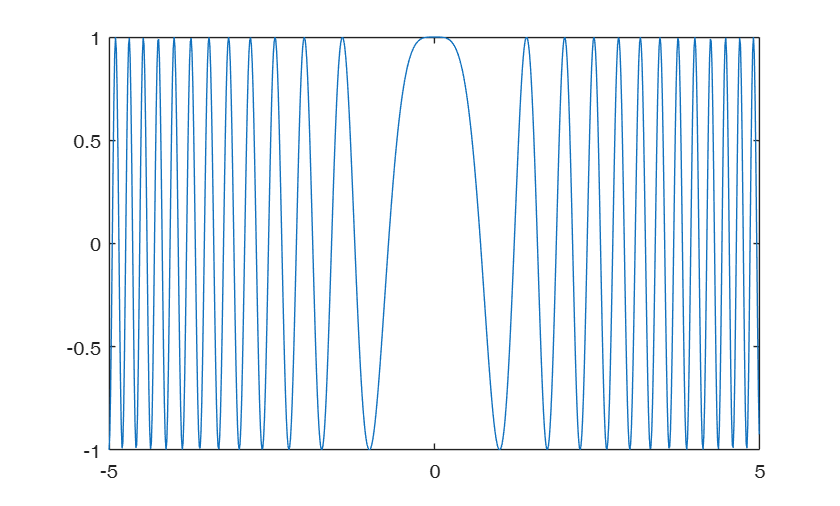

% === 参数设置 ===
close all; clear; clc
j = sqrt(-1);

fs = 100e6;           % 采样频率
ts = 1/fs;
B = 10e6;            % 带宽
fc = 40e6;           % 中心频率
label = 6;

% === LFM脉冲 ===
taup = 10e-6;        % LFM脉宽
Ntau = round(taup * fs);
ttau = (-Ntau/2 : Ntau/2-1) * ts;
lfm = exp(1j*pi*B/taup * ttau.^2);  % 基带LFM脉冲

figure;
plot(ttau*1e6, lfm); % 不妨看看你定义了个咋样的脉冲

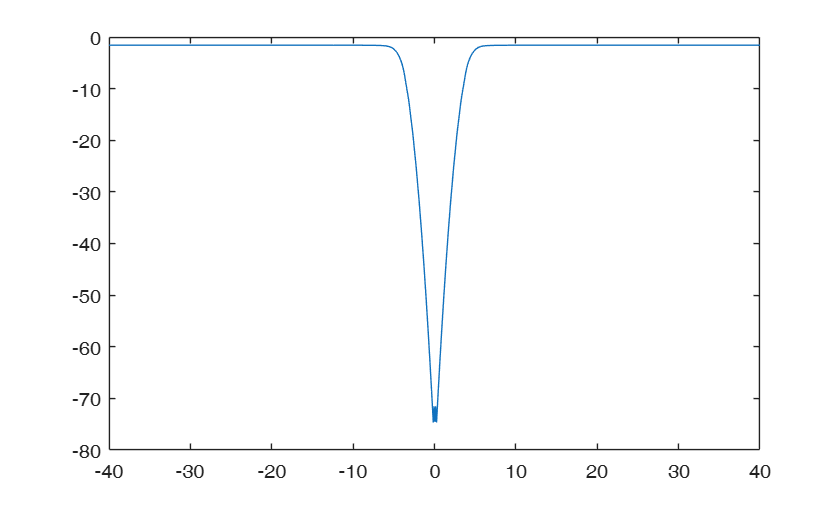

LFM_f = fftshift(fft(lfm)); % 输入信号的傅里叶变换
amp_LFM_f = abs(LFM_f);
phase_LFM_f = unwrap(angle(LFM_f));
F = linspace(-fs/2e6, fs/2e6, length(ttau)); % 频率范围

figure;
plot(F, amp_LFM_f); 

figure;
plot(F, phase_LFM_f);

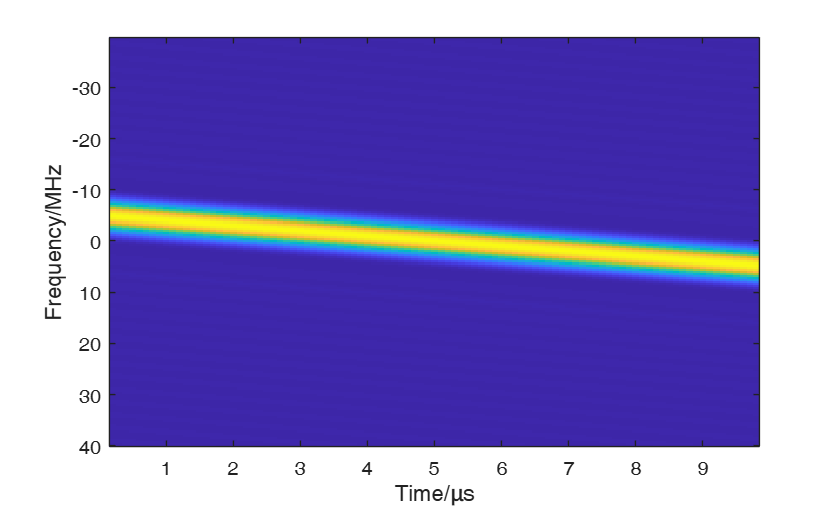


figure;
[S,F,T] = spectrogram(lfm,32,32-8,200,fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
% axis([0 100 -20 20])
ylabel('Frequency/MHz'); xlabel('Time/μs');

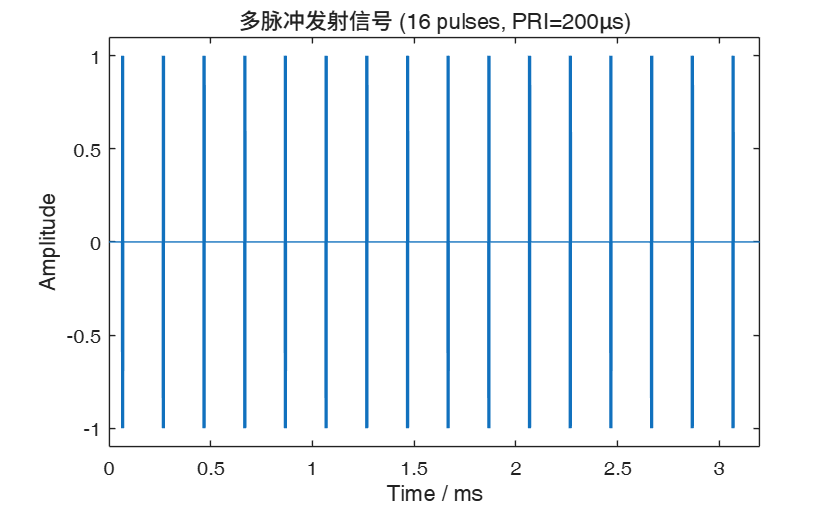



% === 多脉冲参数 ===
Np = 16;                 % 脉冲个数
PRI = 200e-6;            % 脉冲重复间隔 200 μs
PRI_samp = round(PRI * fs);   % 每个PRI的采样点
N_total = Np * PRI_samp;      % 总采样点数
t_total = (0:N_total-1) * ts; % 时间轴



% === 构造发射信号 ===
tx = zeros(1, N_total);
for k = 0:Np-1
    start_idx = k * PRI_samp + 5000;
    tx(start_idx : start_idx + Ntau - 1) = lfm;
end

figure;
plot(t_total*1e3, real(tx));
axis([0 3.2 -1.1 1.1])
xlabel('Time / ms'); ylabel('Amplitude');
title('多脉冲发射信号 (16 pulses, PRI=200μs)');


comp2 = t_total(1:PRI_samp)

comp2 = 1.0e-03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005


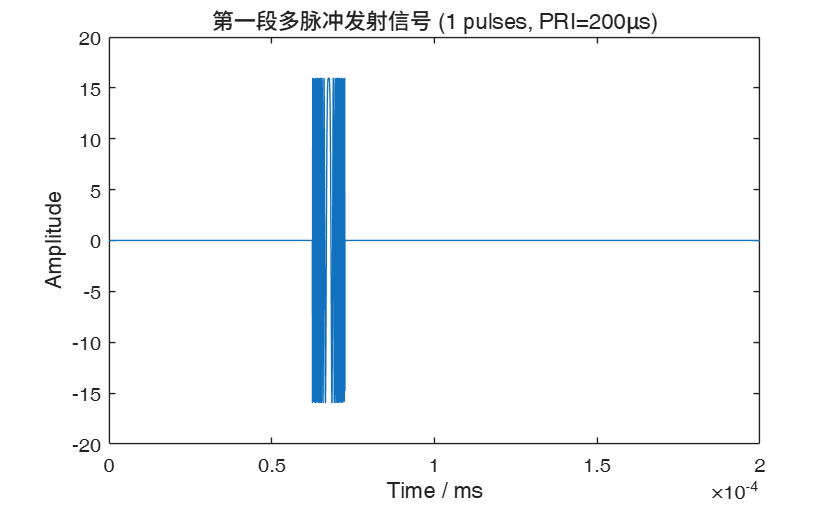

tx_mat = reshape(tx(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
tx_sum = sum(tx_mat, 2);  % 直接复数相加再取幅度
plot(comp2, real(tx_sum));

xlabel('Time / ms'); ylabel('Amplitude');
title('第一段多脉冲发射信号 (1 pulses, PRI=200μs)');

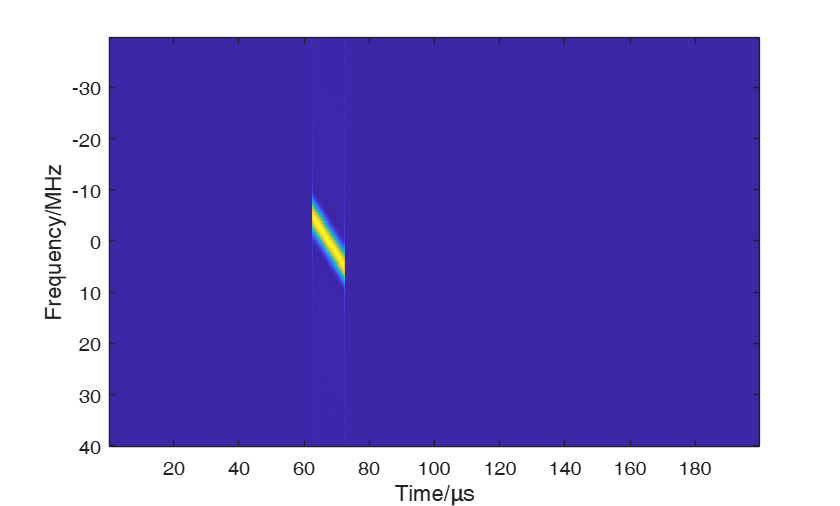


figure;
[S,F,T] = spectrogram(tx_sum,32,32-8,200,fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
% axis([0 100 -20 20])
ylabel('Frequency/MHz'); xlabel('Time/μs');





% === 模拟噪声与干扰 ===
SNR = 15;
JNR = 50;
Bj = 60e6; % 阻塞带宽
fjc = 0;   % 干扰中心频率
data_num = 3 %干扰样本数

data_num = 3

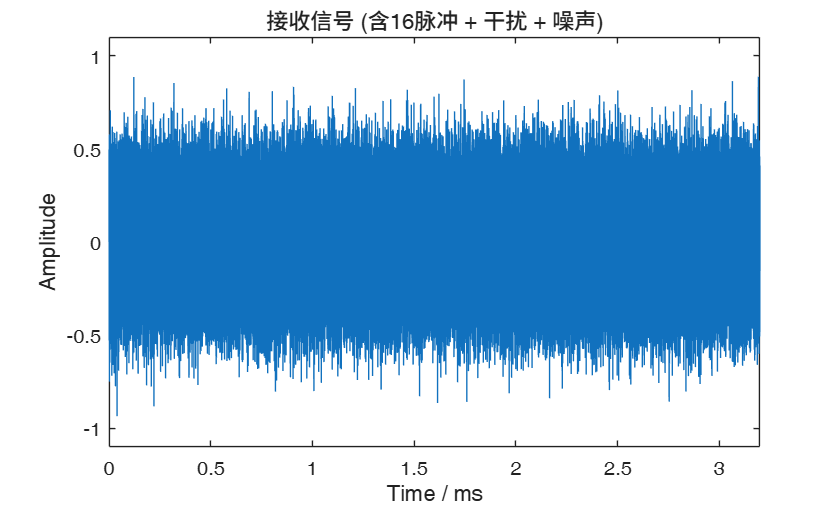

As = 10^(SNR/20);
Aj = 10^(JNR/20);

jam = zeros(data_num,N_total);
for m = 1:data_num
sp = randn([1,N_total]) + 1j*randn([1,N_total]);
sp = sp / std(sp);
white_noise = sp;

% --- 生成阻塞干扰 ---
lpFilt = fir1(34, Bj/fs, chebwin(35,30));
sp_j = filter(lpFilt, 1, sp);
tj = (0:N_total-1)/fs;
sp_j = sp_j .* exp(1j*2*pi*fjc*tj);
jam(m,:) = Aj*sp_j;
end

% --- 加入目标与干扰 ---
range_tar = 1 + round(rand(1)*4000);
jam1 = Aj*sp_j;
pure_echo = As*tx;
rx = As*tx + Aj*sp_j + white_noise;
rx = rx / max(abs(rx));

figure;
plot(t_total*1e3, real(rx));
axis([0 3.2 -1.1 1.1])
xlabel('Time / ms'); ylabel('Amplitude');
title('接收信号 (含16脉冲 + 干扰 + 噪声)');


% === 匹配滤波（脉冲压缩） ===
h = conj(flip(lfm));
y = conv(rx, h);
env = abs(y);

% === 脉冲积累（非相干示例） ===
env_mat = reshape(env(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
env_sum = abs(sum(env_mat, 2));  % 直接复数相加再取幅度
nenv_mat = reshape(y(1:Np*PRI_samp), PRI_samp, Np); % 每列一个脉冲
nenv_sum = sum(nenv_mat, 2); % 非相干积累

% 距离轴
c = 3e8;
rng_axis = (0:PRI_samp-1)*c/(2*fs);
